# LTE 256-QAM Channel Simulation

### Loading Data

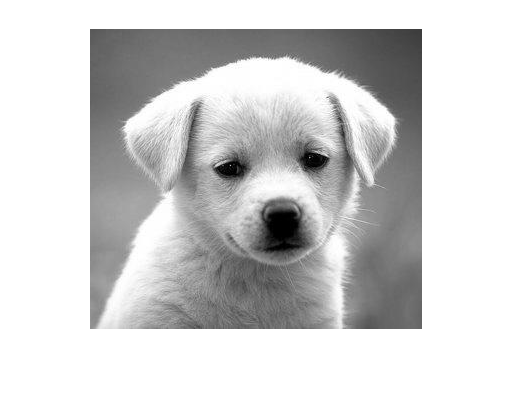

img = imread("B2DBy.jpg");
img = im2gray(img);
imshow(img);

[wavdata,fs] = audioread('testOud4_MONO.wav');

wavdata=wavdata(1:65536);
minim = min(wavdata)

minim = -0.5232

maxim = max(wavdata)

maxim = 0.6644


% Quantization
num_bits=16;
num_levels = 2^num_bits;
step = (maxim- minim)/num_levels;
% levels:
% minim , minim+step, minim +2step, .... , maxim
levels = zeros(1,num_levels);
for i=1:num_levels
    levels(i) = minim+ step*(i-1);
end
quantized =zeros(1,length(wavdata));
for i=1:length(wavdata)
    [val,appropriate_level] =min(abs(wavdata(i) - levels));
    quantized(i) = appropriate_level;
end

%Encoding

encoded = de2bi(quantized-1,num_bits);
encoded = reshape(encoded,1,[]);


received = encoded;


### Encoding for QAM

M = 256;
k = log2(M);

bit_seq = de2bi(img');
bit_seq = reshape(bit_seq, 1, []);
msg = zeros(1, length(bit_seq)/k);
counter = 0;
for i = 1:k:length(bit_seq)
    counter  = counter + 1;
    msg(counter) = bi2de(bit_seq(i:i+k-1));
end


audio_msg = zeros(1, floor(length(audio_bit_seq)/k));

Unrecognized function or variable 'audio_bit_seq'.

counter = 0;
for i = 1:k:length(encoded)
    counter  = counter + 1;
    audio_msg(counter) = bi2de(encoded(i:i+k-1));
end

### QAM Modulation

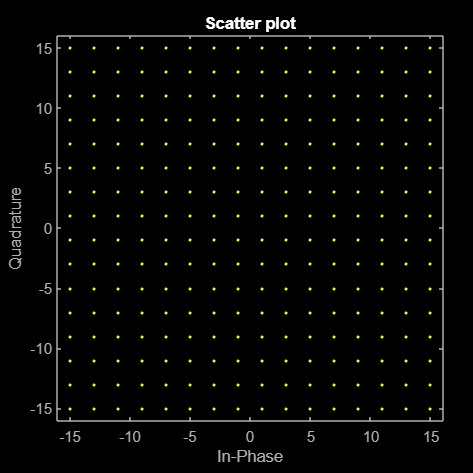

qam_symbols = qammod(msg, M);
scatterplot(qam_symbols);

audio_qam_symbols = qammod(audio_msg, M);
scatterplot(audio_qam_symbols);

**QAM Demodulation**

demodulated_seq = qamdemod(qam_symbols, M);
decoded_seq = [];

for i=1:length(demodulated_seq)
    decoded_seq = [decoded_seq de2bi(demodulated_seq(i),k)];
end

decoded_img = reshape(decoded_seq, [], 8);
reconstructed_img = bi2de(decoded_img);
reconstructed_img = uint8(reshape(reconstructed_img, 332, [])');
imshow(reconstructed_img)

demodulated_audio_seq = qamdemod(audio_qam_symbols, M);
audio_decoded_seq = [];

for i=1:length(demodulated_audio_seq)
    audio_decoded_seq = [audio_decoded_seq de2bi(demodulated_audio_seq(i),k)];
end

% Decoding 
dec = reshape(encoded,[],num_bits);
dec=bi2de(dec)+1;
dec=levels(dec);

plot(dec);

sound(dec', fs);

sum(abs(wavdata - dec'))

#### Passing Data through Rician Channel

ricianchan = comm.RicianChannel( ...
    'SampleRate',1e6, ...
    'PathDelays',[0.0 0.5 1.2]*1e-6, ...
    'AveragePathGains',[0.1 0.5 0.2], ...
    'KFactor',2.8, ...
    'DirectPathDopplerShift',5.0, ...
    'DirectPathInitialPhase',0.5, ...
    'MaximumDopplerShift',50, ...
    'DopplerSpectrum',doppler('Bell', 8), ...
    'RandomStream','mt19937ar with seed', ...
    'Seed',73, ...
    'PathGainsOutputPort',true);
s_rician = ricianchan(qam_symbols');

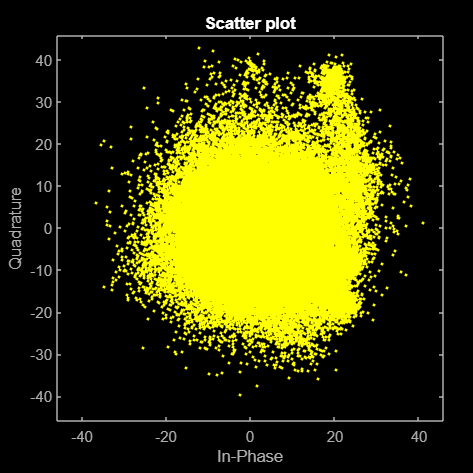

scatterplot(s_rician);

#### Deomdulation

demodulated_seq = qamdemod(s_rician', M);
decoded_seq = [];

for i=1:length(demodulated_seq)
    decoded_seq = [decoded_seq de2bi(demodulated_seq(i),k)];
end

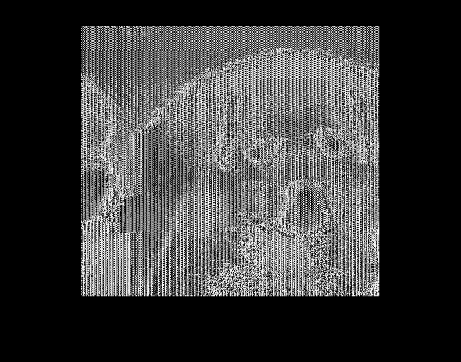

decoded_img = reshape(decoded_seq, [], 8);
reconstructed_img = bi2de(decoded_img);
reconstructed_img = uint8(reshape(reconstructed_img, 332, [])');
imshow(reconstructed_img)

#### Passing Data through Rayleigh Channel

rayleighchan = comm.RayleighChannel( ...
    'SampleRate',10e6, ...
    'PathDelays',[0 1.5e-4], ...
    'AveragePathGains',[2 3], ...
    'NormalizePathGains',true, ...
    'MaximumDopplerShift',30, ...
    'DopplerSpectrum',{doppler('Gaussian',0.6),doppler('Flat')}, ...
    'RandomStream','mt19937ar with seed', ...
    'Seed',22, ...
    'PathGainsOutputPort',true);
s_rayleigh = ricianchan(qam_symbols');

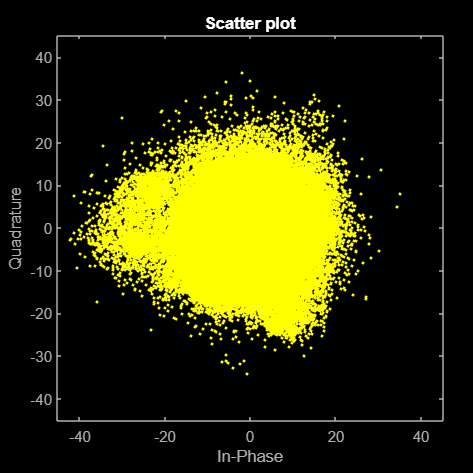

scatterplot(s_rayleigh);

#### Deomdulation

demodulated_seq = qamdemod(s_rayleigh', M);
decoded_seq = [];

for i=1:length(demodulated_seq)
    decoded_seq = [decoded_seq de2bi(demodulated_seq(i),k)];
end


decoded_img = reshape(decoded_seq, [], 8);
reconstructed_img = bi2de(decoded_img);
reconstructed_img = uint8(reshape(reconstructed_img, 332, [])');
imshow(reconstructed_img)

## BER vs SNR graphs

snr = 0 :10;
AWGN = BER_AWGN(bit_seq,qam_symbols,M,k);
Ray = BER_Rayleigh(bit_seq,qam_symbols,M,k);
Rician = BER_RicianChannel(bit_seq,qam_symbols,M,k);

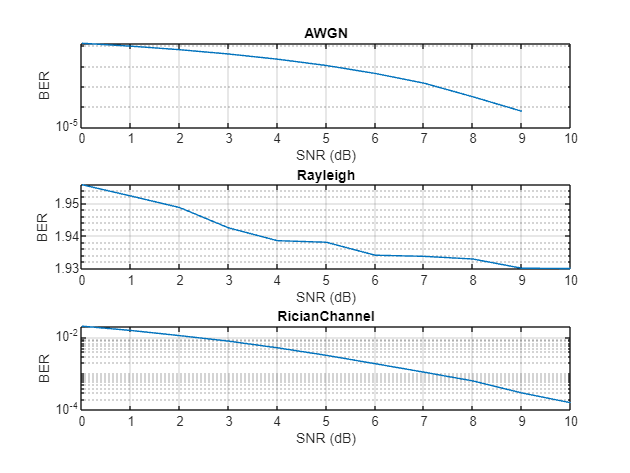


figure;
subplot(3,1,1);
subplot(3,1,1);
semilogy(snr,AWGN(snr+1));
title('AWGN')
xlabel('SNR (dB)')
ylabel('BER')
xlim([0 10])
grid on
subplot(3,1,2);
semilogy(snr,Ray(snr+1));
title('Rayleigh')
xlabel('SNR (dB)')
ylabel('BER')
xlim([0 10])
grid on
subplot(3,1,3);
semilogy(snr,Rician(snr+1));
title('RicianChannel')
xlabel('SNR (dB)')
ylabel('BER')
xlim([0 10])
grid on

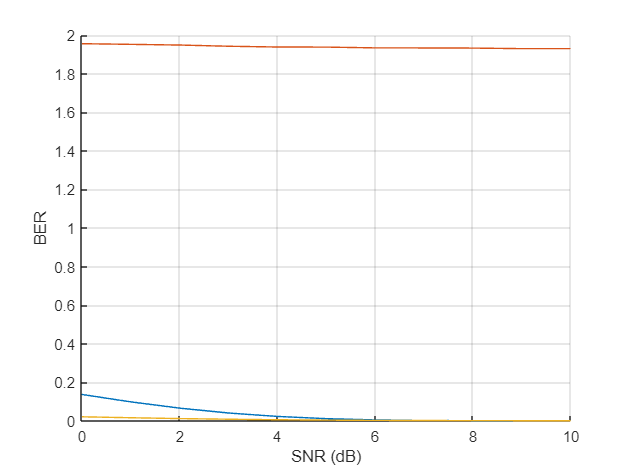

figure;
hold on;
semilogy(snr,AWGN(snr+1));
semilogy(snr,Ray(snr+1));
semilogy(snr,Rician(snr+1));
xlabel('SNR (dB)')
ylabel('BER')
grid on
hold off;